%test galactic

## SES

#### UTS*Area load cases 

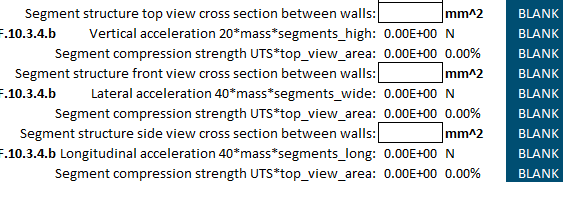

#### Module Volume

[https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf](https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf) 

EneModWidth = 20.3/1000;%(m)
EneSegHeight =  105.6/1000;%(m)
EneModDepth = 69.5/1000;%(m)
ModuleWeight = 278/1000;%kg

### Segment Dimensions

SegmentCasingHeight = EneSegHeight;%m
EneSegmentDepth = 6*EneModDepth;%num moduleSs*moduleDepth*mmtoinches + flange added length - hole locatoin
EneSegmentWidth = EneModWidth * 4;
GaroliteThickness = 1/8*25.4/1000;
SegmentModulesWeight = ModuleWeight*23%kg

SegmentModulesWeight = 6.3940

### Segment Cross Sectional Areas

TopCrossSecArea = EneSegmentDepth*GaroliteThickness*2;
WidthCrossSecArea = EneSegmentDepth*GaroliteThickness*2;
DepthCrossSecArea = EneSegmentWidth*GaroliteThickness*2 + EneSegHeight*GaroliteThickness*2;

### Segment Forces and Stresses

TopCrossSecForce = SegmentModulesWeight*20*9.8;%in newtons
WidthCrossSecForce = 6*SegmentModulesWeight*40*9.8;%in newtons
DepthCrossSecForce = SegmentModulesWeight * 40 * 9.8;

TopStress = TopCrossSecForce/TopCrossSecArea

TopStress = 4.7328e+05

WidthStress = WidthCrossSecForce/WidthCrossSecArea

WidthStress = 5.6794e+06

DepthStress = DepthCrossSecForce/DepthCrossSecArea

DepthStress = 2.1130e+06

SafetyFactorCasing = garoliteStrength/WidthStress

SafetyFactorCasing = 46.1320

### Garolite Properties

garoliteStrength = 38000*psiTopPascal;%262,000,000pa
psiTopPascal = 6894.76;
garoliteFlexuralModulus = 2400* 1000 * psiTopPascal;

### Bolt calculations

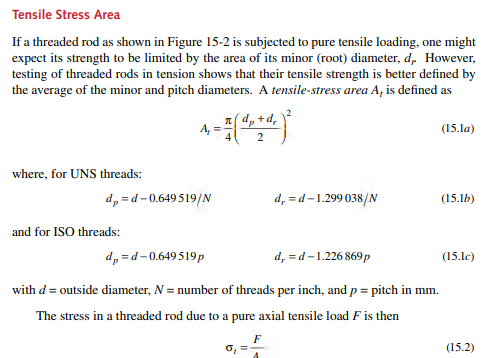

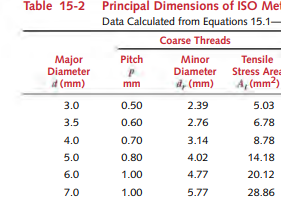

dia = 6;
pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000;%Converts to Meters
exampleGr5Tensile = 827370875;%Converted from psi
MaxTensileForFastener = exampleGr5Tensile*ABTMeters %newtons

MaxTensileForFastener = 1.6649e+04

SafetyFactorBoltTension = MaxTensileForFastener*2/TopCrossSecForce

SafetyFactorBoltTension = 26.5707

SafetyFactorVoltShear = WidthCrossSecForce*12/MaxTensileForFastener

SafetyFactorVoltShear = 10.8390

### Tear out 

[https://laminatedplastics.com/g-10.pdf](https://laminatedplastics.com/g-10.pdf) 

BoltDistanceFromEdge = 8/1000;%mm  realistic distance from edge
maxTearoutForce = BoltDistanceFromEdge*garoliteThickness*garoliteStrength

maxTearoutForce = 1.3310e+04

### Flange Bonding

fr4BondStrength = 2200*psiTopPascal;
MinFlangeBondArea = DepthCrossSecForce/fr4BondStrength

MinFlangeBondArea = 1.6524e-04

DepthRestrictingBondArea = garoliteThickness * 80/1000

DepthRestrictingBondArea = 5.0800e-04

SideBondArea = 0.02* garoliteThickness*2

SideBondArea = 2.5400e-04

bondMaxForce = fr4BondStrength * (DepthRestrictingBondArea + SideBondArea)

bondMaxForce = 1.1558e+04

### Lid Deflection from 20g Loading

Packload = TopCrossSecForce ;
EneLidSegmentDepth = 6*EneModDepth + 0.082 -0.022;%
vmax = Packload * (EneLidSegmentDepth^4)/384/(garoliteFlexuralModulus)/((0.08*0.00635^3)/12)

vmax = 0.0060

## Euler-Johnson buckilng limits

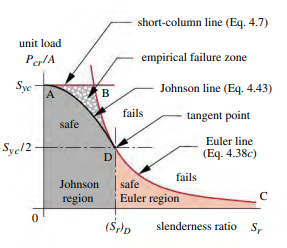

MomentOfInertiaSideWalls = 2*( (EneSegmentWidth/2+garoliteThickness/2)^2 * GaroliteThickness*(EneSegHeight+(2*GaroliteThickness))) + (garoliteThickness^3*SegmentCasingHeight/12)

MomentOfInertiaSideWalls = 1.3645e-06

% half width to get to walls + half of garolite thickness = centroid
% distance away, * area sidewall + garolite thickness^3(height) * segment height(width) 

MomentOfInertiaBottom = (garoliteThickness/2 + EneSegHeight/2)^2 * GaroliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaBottom = 8.0950e-07

MomentOfInertiaLid = (garoliteThickness/2 + EneSegHeight/2+(15/1000))^2 * GaroliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaLid = 1.3004e-06


ixx = MomentOfInertiaLid + MomentOfInertiaBottom + MomentOfInertiaSideWalls

ixx = 3.4744e-06

RadiusOfGyration = sqrt(ixx/DepthCrossSecArea)

RadiusOfGyration = 0.0541


SlendernessRatioCasing = EneSegmentDepth/RadiusOfGyration

SlendernessRatioCasing = 7.7050

SlendernessRatioForHalfStrength = pi*sqrt(2*garoliteFlexuralModulus/garoliteStrength)

SlendernessRatioForHalfStrength = 35.3085

MaxForceJohnson = DepthCrossSecArea *(garoliteStrength-(1/garoliteFlexuralModulus *(garoliteStrength*SlendernessRatioCasing/2/pi)^2))

MaxForceJohnson = 3.0338e+05

### Passive Thermal Properties

SurfaceArea = EneSegmentDepth*EneSegmentWidth*2 + EneSegHeight*EneSegmentDepth*2;
heatFluxPerC = 1/garoliteThickness * 0.288 * SurfaceArea

heatFluxPerC = 7.0658